## Label the units declared as univariate outliers in the boxplot  

#### Example 1: input Y is a vector and no groups.

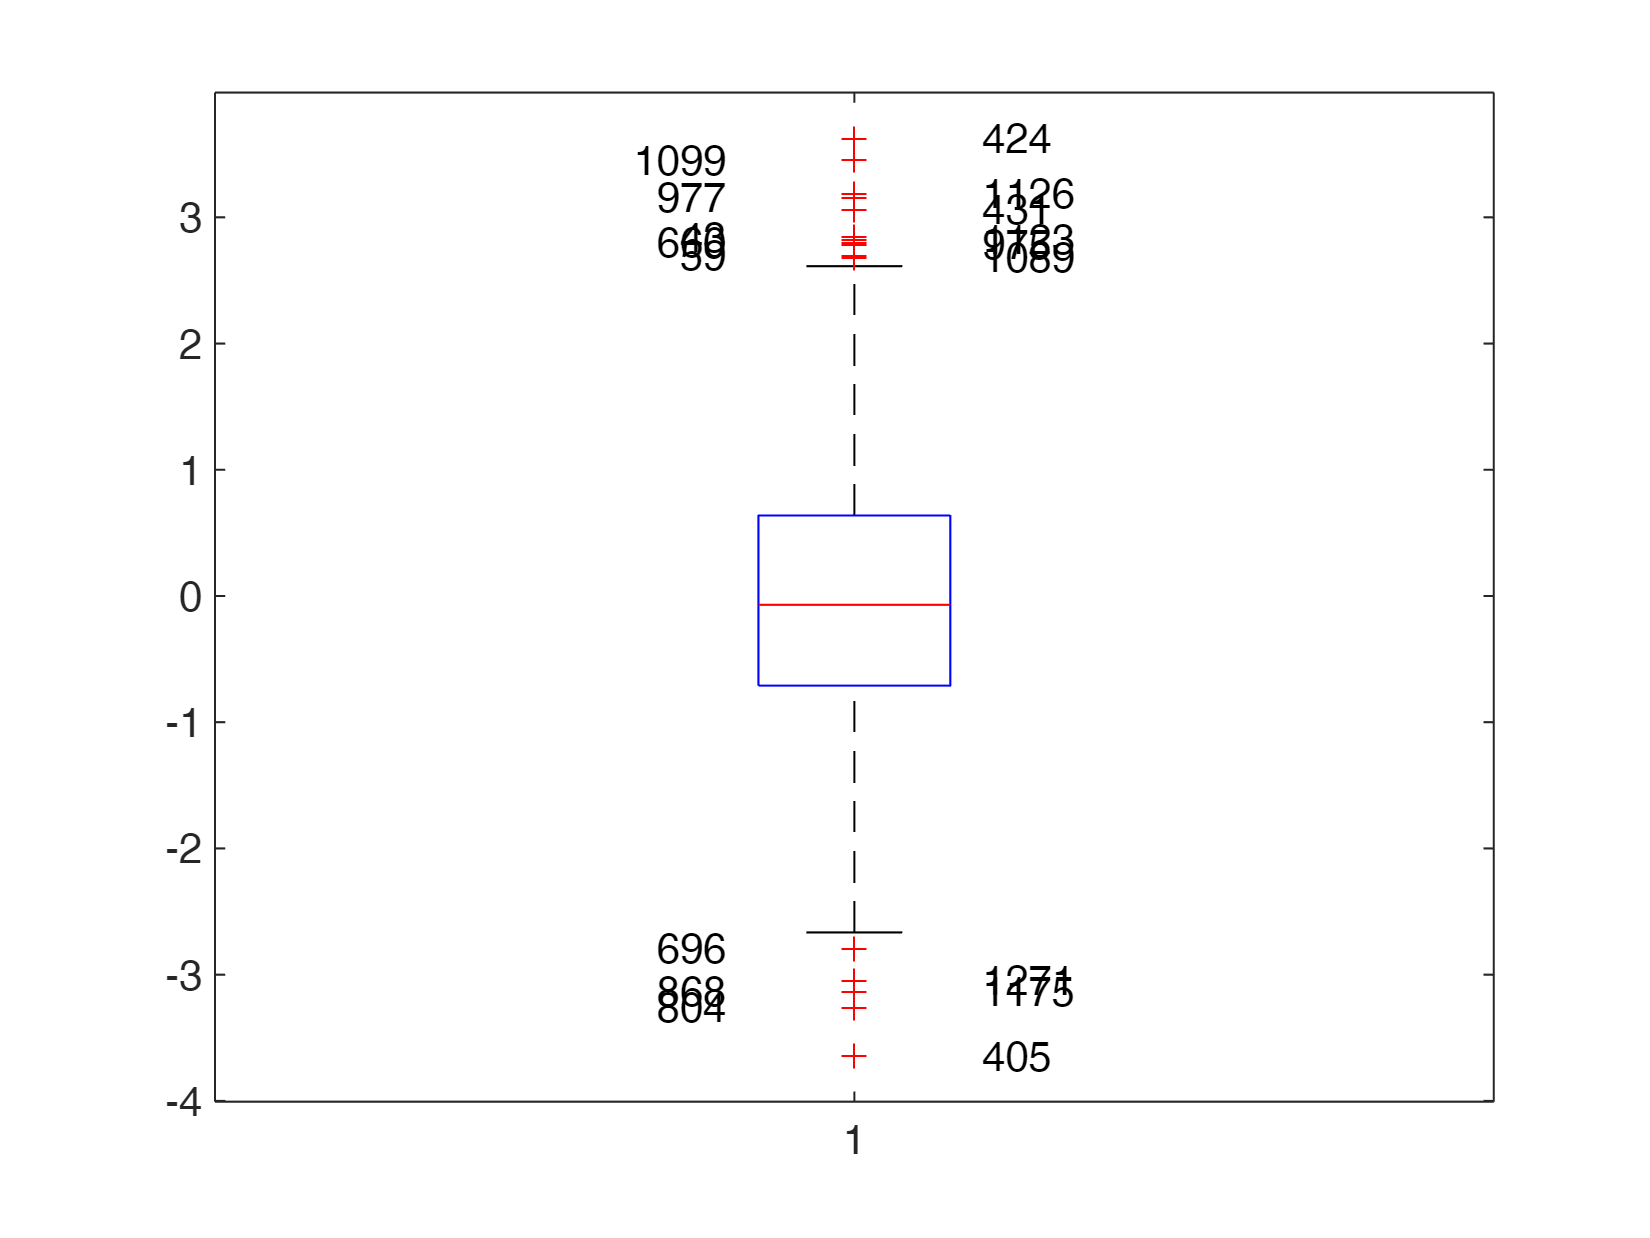

    % boxplot is called with input variable Y as a vector and there is no
    % grouping variable.
    rng(2)
    y=randn(1300,1);
    boxplot(y)
    add2boxplot(y);

####  Example 2: Y is a matrix and there is no grouping variable.

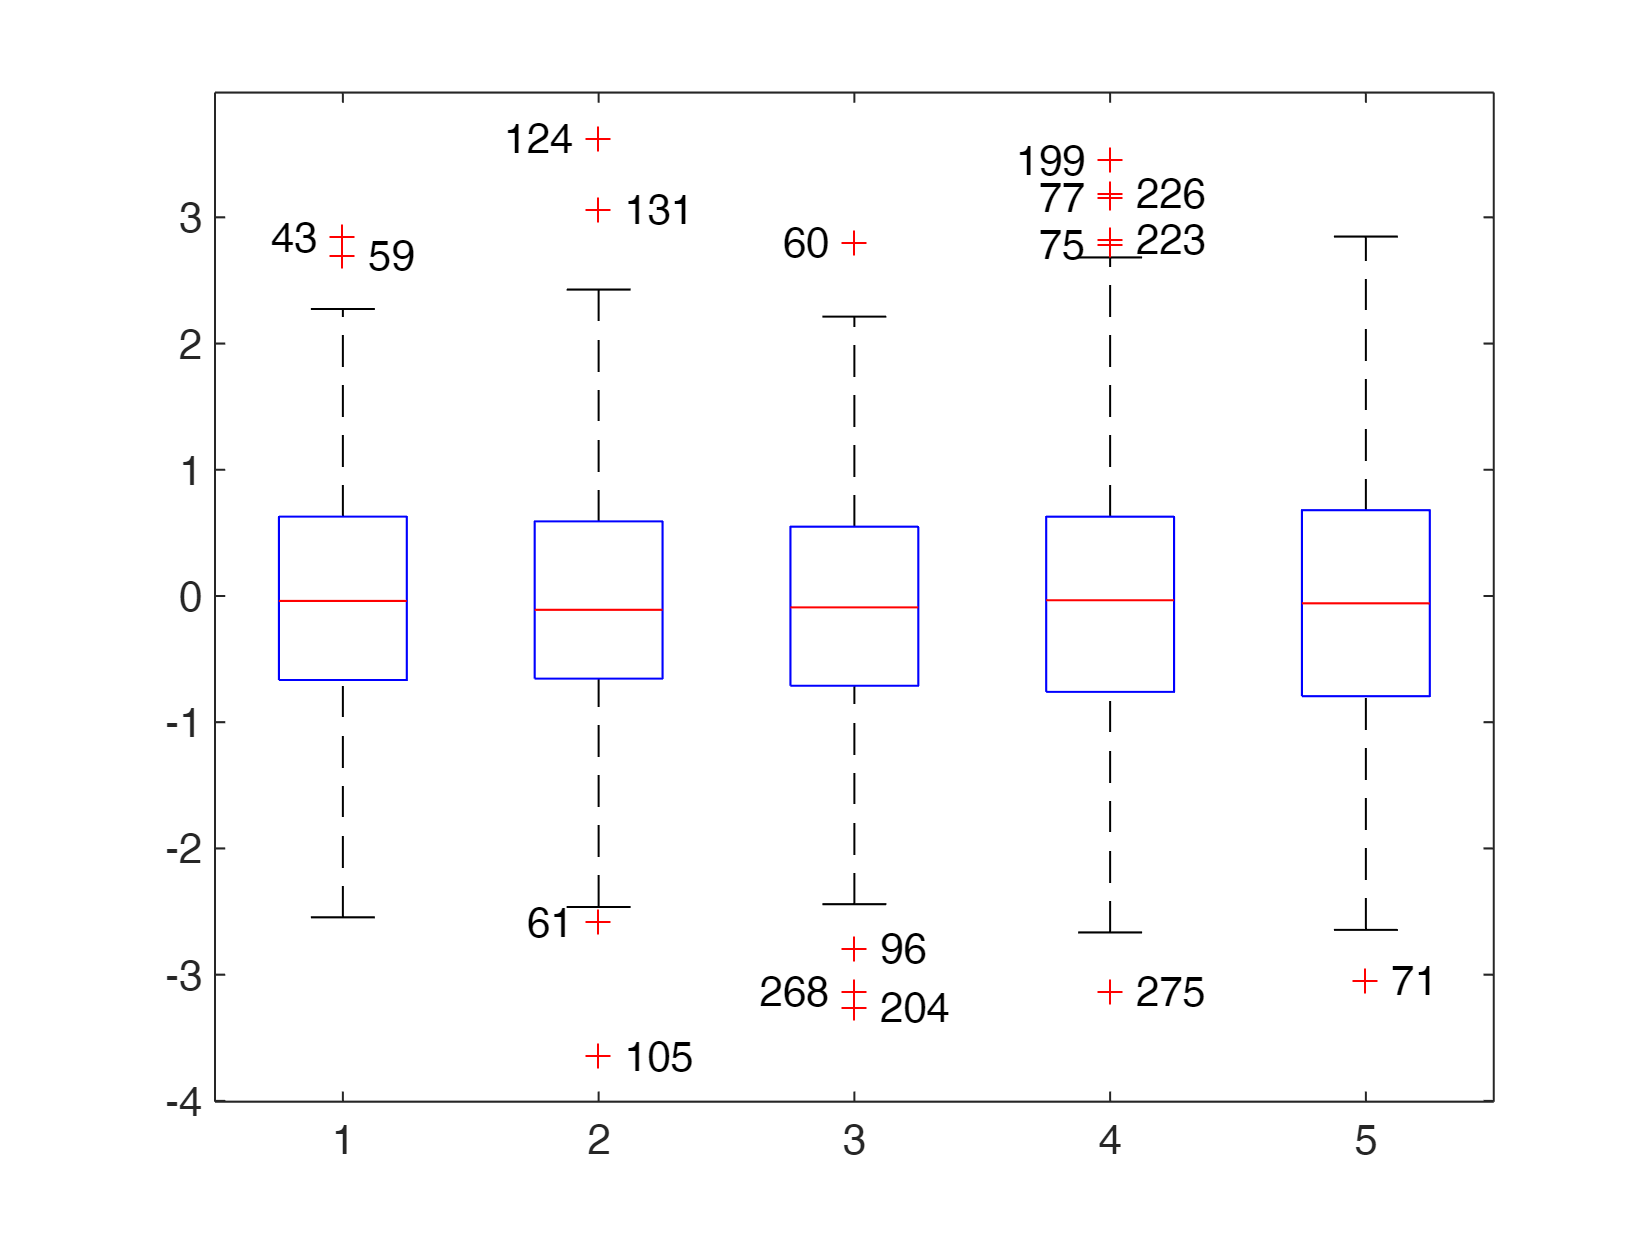


       % boxplot is called with input variable Y as a matrix and there is no
    % grouping variable.
    rng(2)
    y=randn(300,5);
    boxplot(y)
    add2boxplot(y);

####   Example 3: Y is a vector and there is a grouping variable.

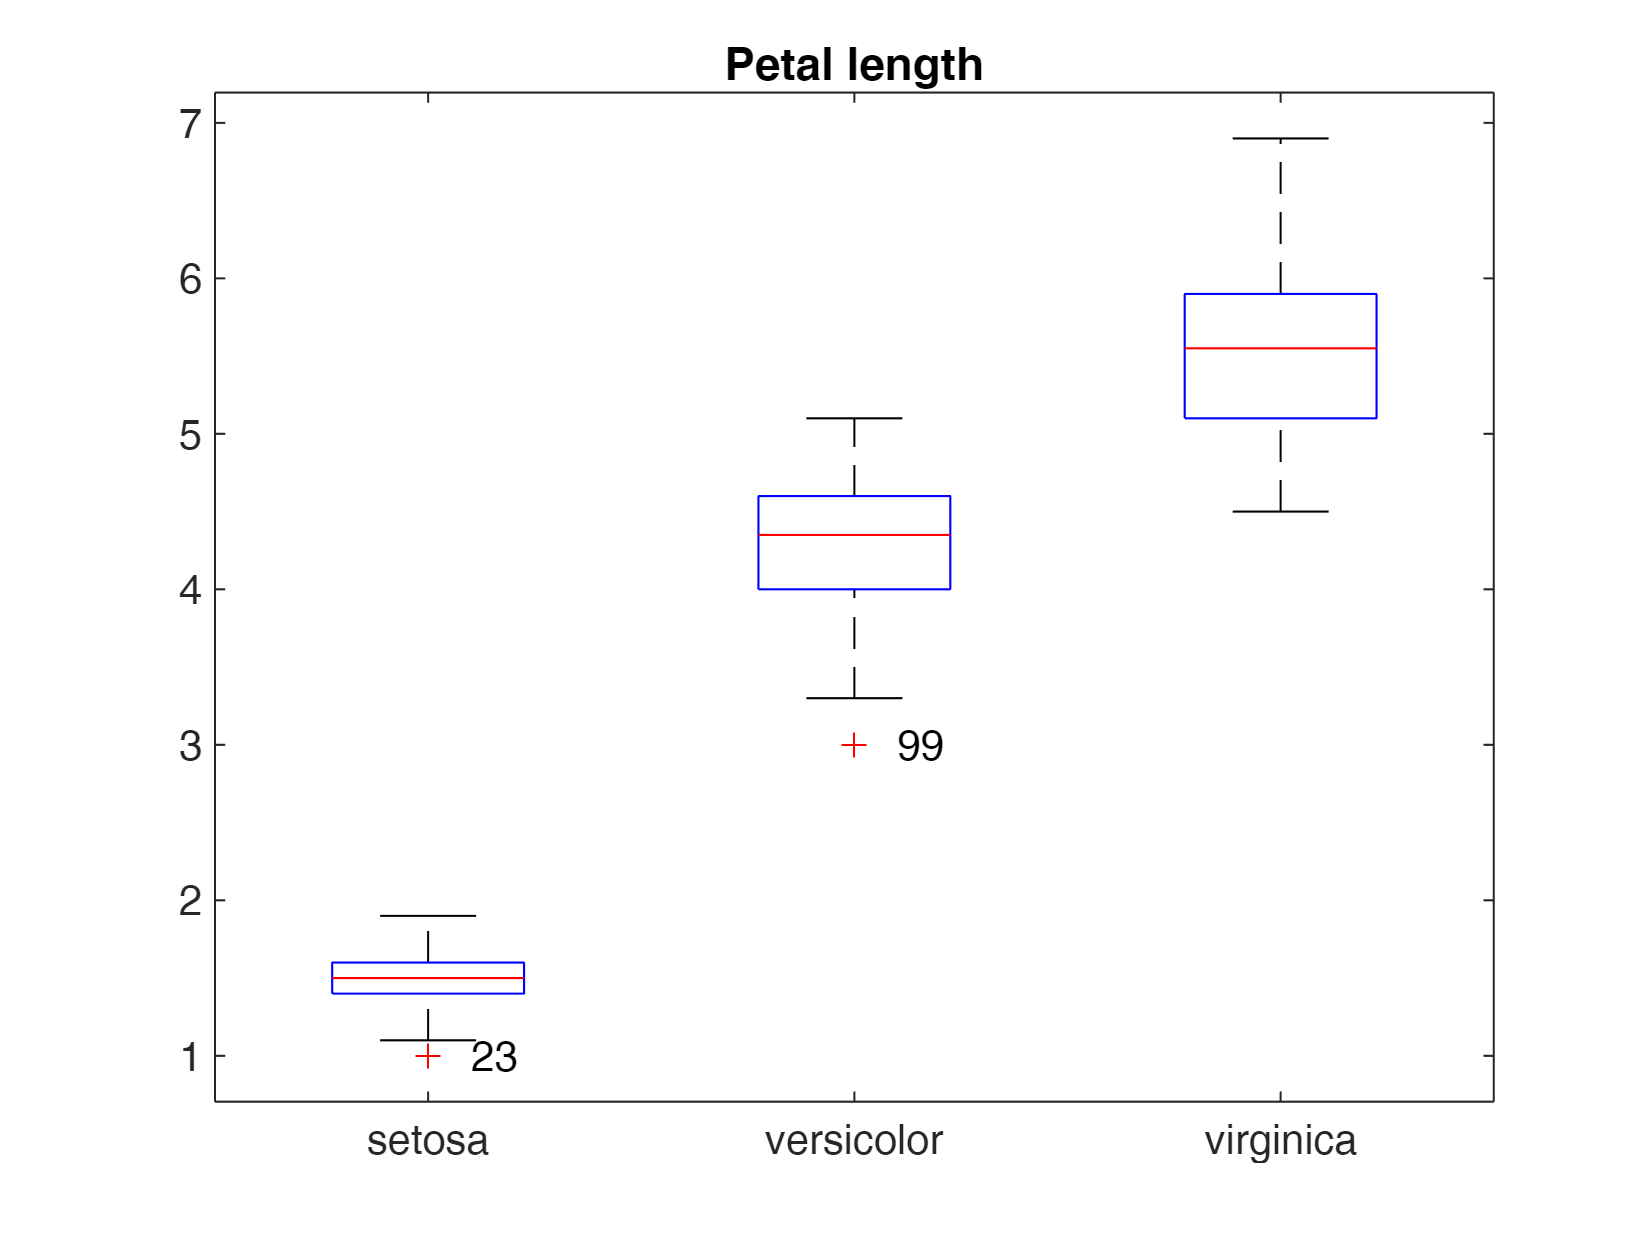

    % boxplot is called with input variable Y as a vector and there is a
    % grouping variable.
    load fisheriris
    nam={'Sepal length','Sepal width','Petal length','Petal width'};
    j=3;
    boxplot(meas(:,j),species)
    add2boxplot(meas(:,j),species)
    title(nam(j))

####  Example 4: Y is table.

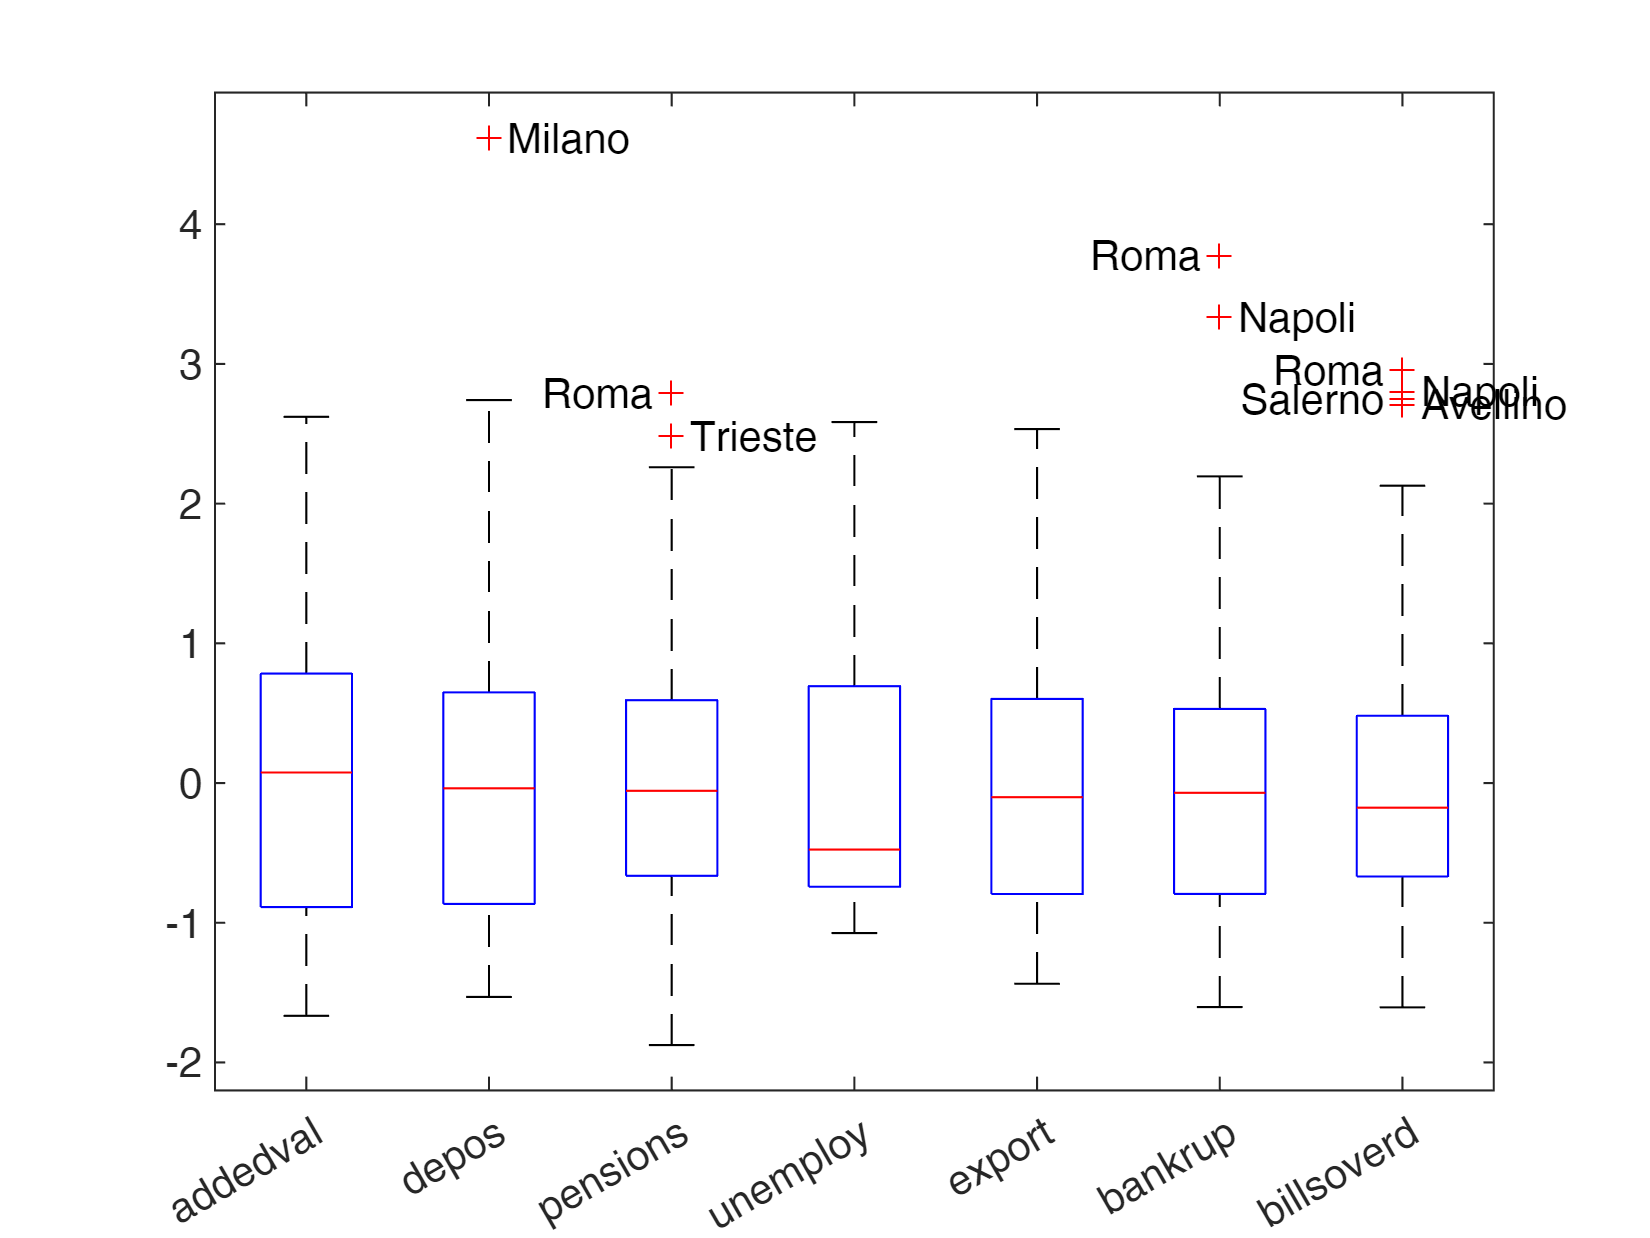

    % load dataset referred to Italian cities about quality of life.
    load citiesItaly.mat
    Yst=citiesItaly;
    Yst{:,:}=zscore(citiesItaly{:,:});
    boxplot(Yst{:,:},'Labels',citiesItaly.Properties.VariableNames,'Jitter',0);
    add2boxplot(Yst)

#### Example 5: Y is table and there are subplots.

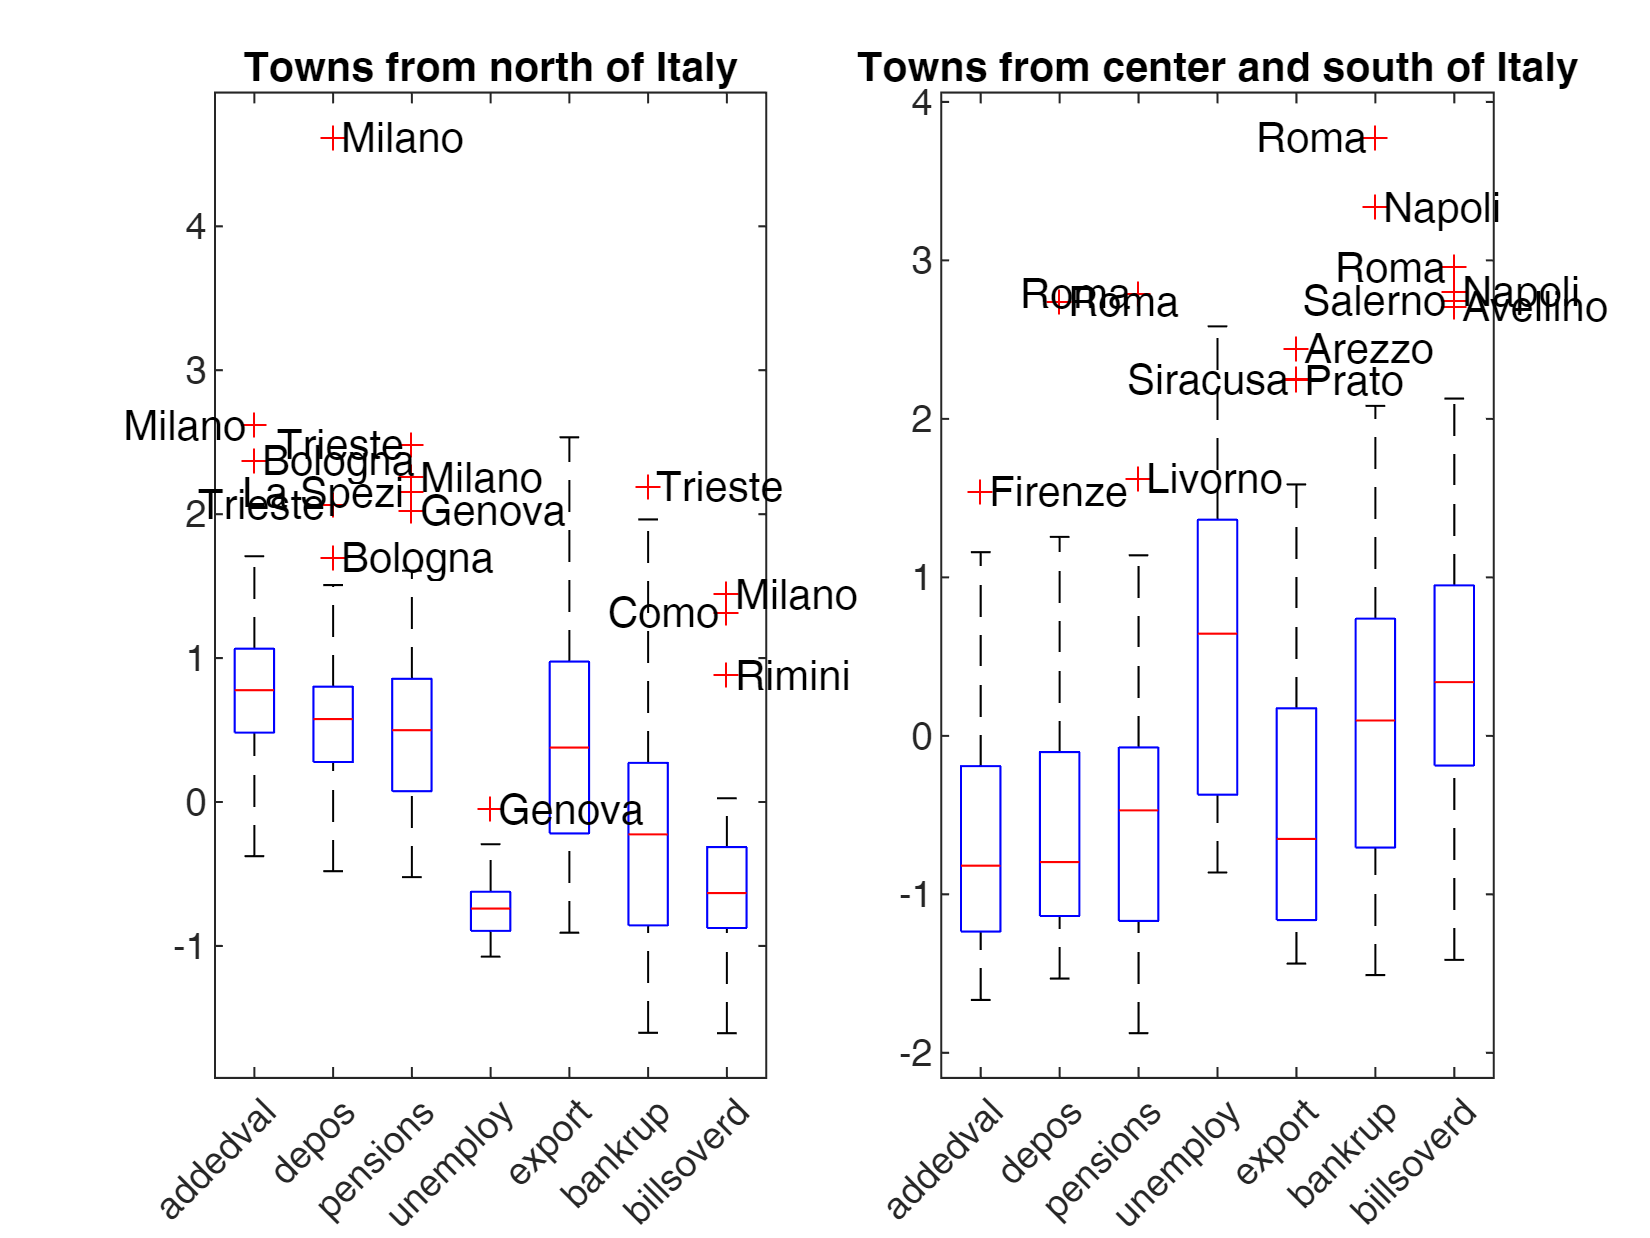

    load citiesItaly.mat
    close all
    citiesItaly{:,:}=zscore(citiesItaly{:,:});
    
    subplot(1,2,1)
    Yst=citiesItaly{1:46,:};
    Ystt=citiesItaly(1:46,:);
    boxplot(Yst,'Labels',citiesItaly.Properties.VariableNames,'Jitter',0);
    add2boxplot(Ystt)
    title("Towns from north of Italy")

    subplot(1,2,2)
    Yst1=citiesItaly{47:end,:};
    Yst1t=citiesItaly(47:end,:);
    boxplot(Yst1,'Labels',citiesItaly.Properties.VariableNames,'Jitter',0);
    add2boxplot(Yst1t)
    title("Towns from center and south of Italy")

For additional information on function add2boxplot see [http://rosa.unipr.it/FSDA/add2boxplot.html](http://rosa.unipr.it/FSDA/add2boxplot.html) 